assembly=assemblyortho;
%assembly=assemblystat;
%assembly=assemblyraw;
nbassemblies=length(assembly);

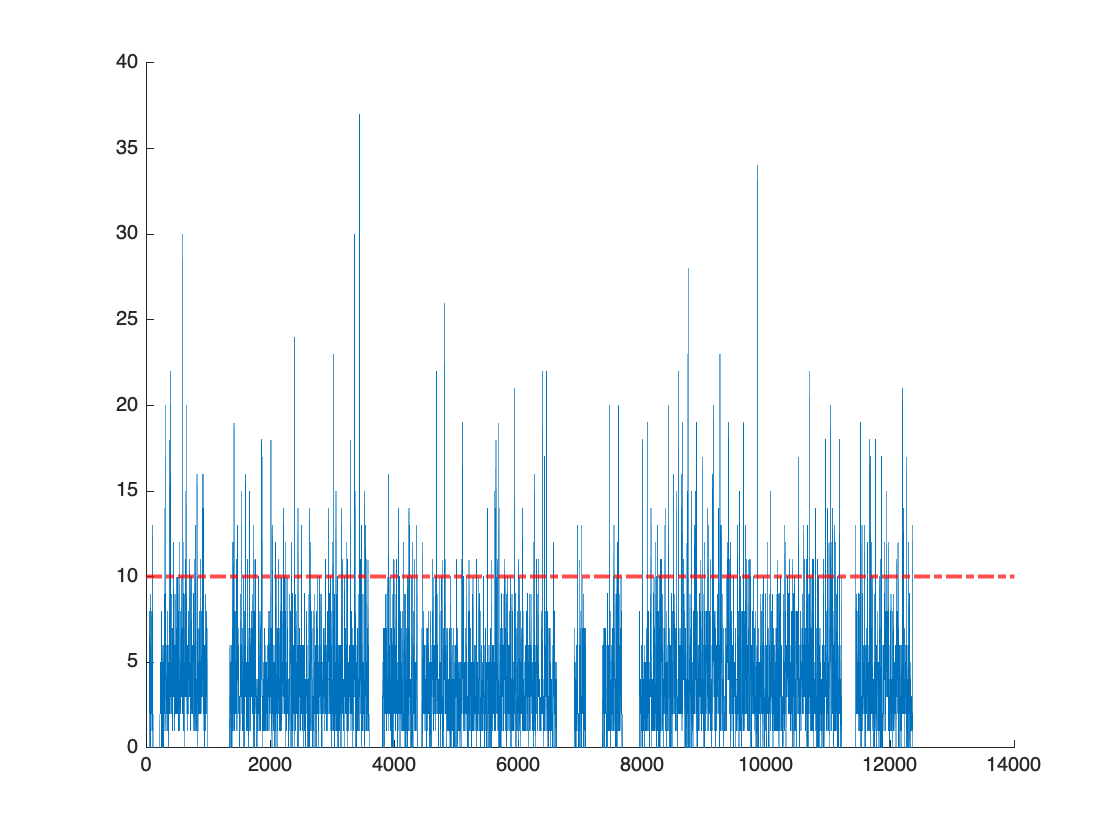


figure
smMAct=smoothdata(MAct,'gaussian',5);
plot (MAct)
yline(sce_n_cells_threshold,'-.r','LineWidth',2);
box off
axis ([0 Nz 0 max(MAct)])
namegraph=[namefull 'SCE.png'];
exportgraphics(gcf,namegraph,'Resolution',300);

close gcf
% nbassemblies=length(assemblyortho);
% subplot(2,1,2)
%     % for i = 1:length(TRace)
%     %     line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
%     % end
%     for i=1 :length(assemblyortho)
% 
%         plot(CellCl(i,:),'Color','red')
%         hold on
%     end
%     hold off

% 
% % Create color map for different cell colors
% colorMap = lines(nbassemblies);
% 
% % Plot raster plot
% figure;
% hold on;
% 
% for i = 1:nbassemblies
%     % Find indices of spikes for the current cell
%     % [trialIndices, spikeIndices] = find(spikeData(:, i, :));
% 
%     % Plot spikes for the current cell with the corresponding color
%     tmp=CellCl(i,:);
%     t=linspace(1,length(CellCl),length(CellCl));
%     bar(t,tmp+i-1);
%     hold on
% end
% hold off

% Customize the plot
% xlabel('Time');
% ylabel('Trial');
% title('Raster Plot of Neuronal Activity');
% colormap(colorMap);
% colorbar('Ticks', linspace(0, 1, numCells), 'TickLabels', 1:numCells);
% xlim([0, maxSpikesPerTrial]);
% ylim([1, numTrials]);

% idortho=cellfun(@length,assemblyortho);

% imagesc(Tr1b(assemblyortho{1},:));

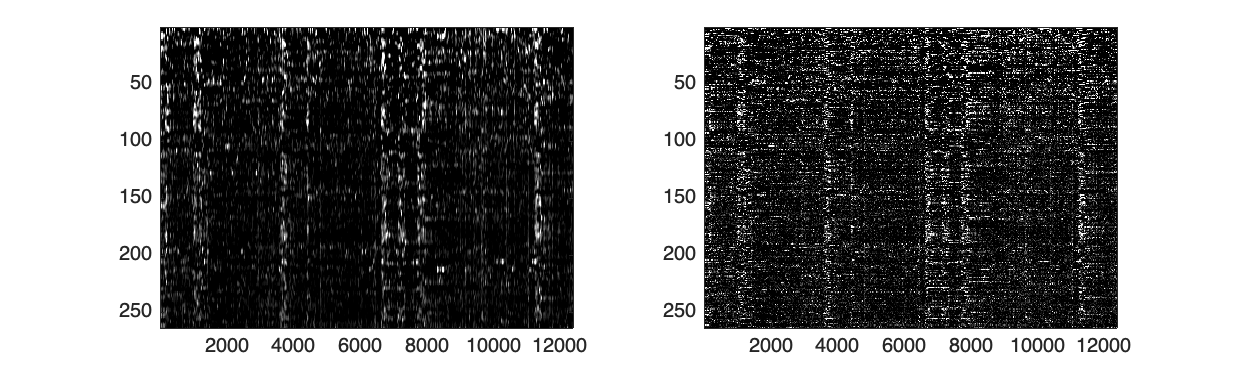

%raw image cells not sorted
smtrace=smoothdata(Tr1b,1,'gaussian',5);
smtrace=smoothdata(smtrace,2,'gaussian',5);
subplot(1,2,1)
imagesc(smoothdata(smtrace))
colormap gray
clim ([0 0.2])
subplot(1,2,2)
imagesc(Tr1b)
colormap gray
clim ([0 0.2])
%tightfig(gcf)
set(gcf, 'Position', [0, 0, 1000, 300]);

namegraph=[namefull 'rastersmooth.png'];
exportgraphics(gcf,namegraph,'Resolution',300);
close gcf


%axis image
% hold on
% Y=zeros(1,length(TRace))-10;
%     for i = 1:length(TRace)
%         % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
%         line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.2);
%         %text(TRace(i),1,'*','FontSize',20);
%     end
%     hold off

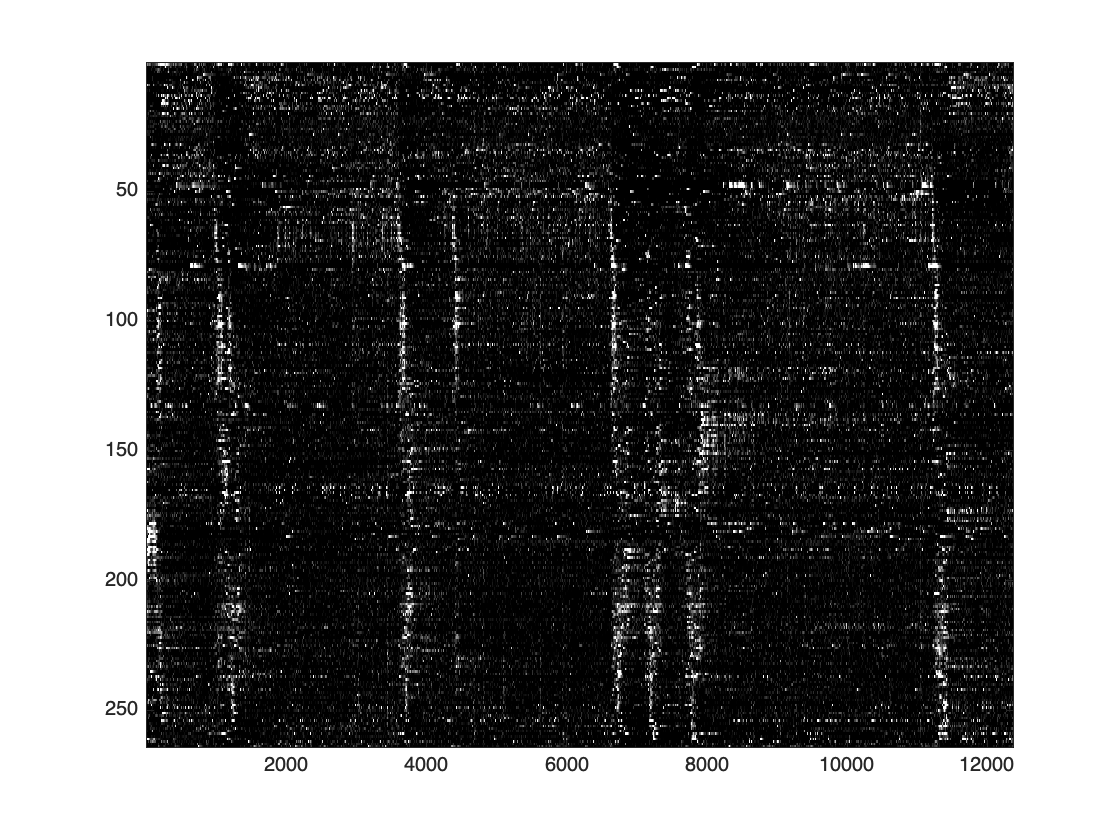

% TSNE=tsne(Tr1b,"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",30,"Distance","correlation");
% [B , index]=sort(TSNE);
% figure
% 
% imagesc(Tr1b(index,:))
% hold on
% colormap gray
% clim ([0 0.4])
% % plot (-speed-2,'Color','k','LineWidth',2)
%  hold off

% set(gcf, 'Position', [0, 0, 1000, 1000]);
% axis ([0 Nz -21 NCell])
 % name=[namefull 'tsne.png'];
 % exportgraphics(gcf,name,'Resolution',300);

% %raster cells tSNE sorted
% TSNE=tsne(Tr1b,"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
%     "Distance","correlation",'Perplexity',50,'Exaggeration',20);
% [B , index]=sort(TSNE);
% %raster t-sne all trace
% figure
% smtrace=smoothdata(Tr1b,1,'gaussian',10);
% smtrace=smoothdata(smtrace,2,'gaussian',5);
% 
% imagesc(smtrace(index,:))
% colormap hot
% axis xy
% clim ([0 0.3])
% hold on
% %plot (speed-20,'Color','k','LineWidth',2)
% hold off
% set(gcf, 'Position', [0, 0, 1000, 1000]);
% axis ([0 Nz -21 NCell])
% hold on
% for i = 1:length(TRace)
%     % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
%     line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.2);
%     %text(TRace(i),1,'*','FontSize',20);
% end
% 
% hold off

%raster cells tSNE sorted rest period
TSNE=tsne(Tr1b(:,WinRest),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
    "Distance","correlation",'Perplexity',50,'Exaggeration',20);
[B , index]=sort(TSNE);

figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))

colormap hot
axis xy
clim ([0 0.3])
hold on
plot (speedraw-20,'Color','k','LineWidth',2)
hold off
set(gcf, 'Position', [0, 0, 1000, 1000]);
axis ([0 Nz -21 NCell])

namegraph=[namefull 'Fluo_tSNEwinrest_sorted_rastersmooth.png'];
exportgraphics(gcf,namegraph,'Resolution',300);
close gcf

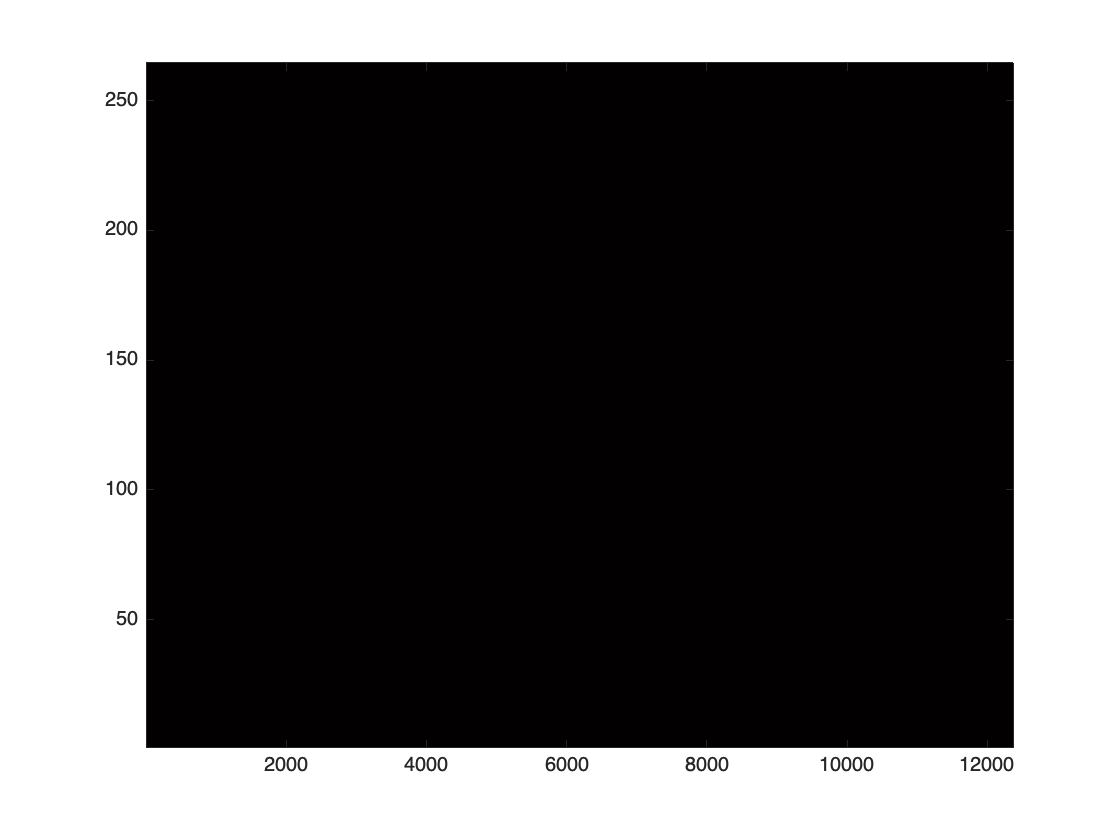

%raster cells tSNE sorted run period
TSNE=tsne(Tr1b(:,WinActive),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
    "Distance","correlation",'Perplexity',4,'Exaggeration',100);
% TSNE=tsne(FR,"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
%     "Distance","correlation",'Perplexity',4,'Exaggeration',100);
[B , index]=sort(TSNE);
%figure;scatter(TSNE(:,1),TSNE(:,2),'DisplayName','TSNE')
figure
smtrace=smoothdata(Tr1b,1,'gaussian',10);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace(index,:))

colormap hot
axis xy
% clim ([0 200])
hold on

plot (speed-20,'Color','k','LineWidth',2)
namegraph=[namefull 'Fluo_tSNEwinactive_sorted_rastersmooth.png'];
exportgraphics(gcf,namegraph,'Resolution',300);
close gcf

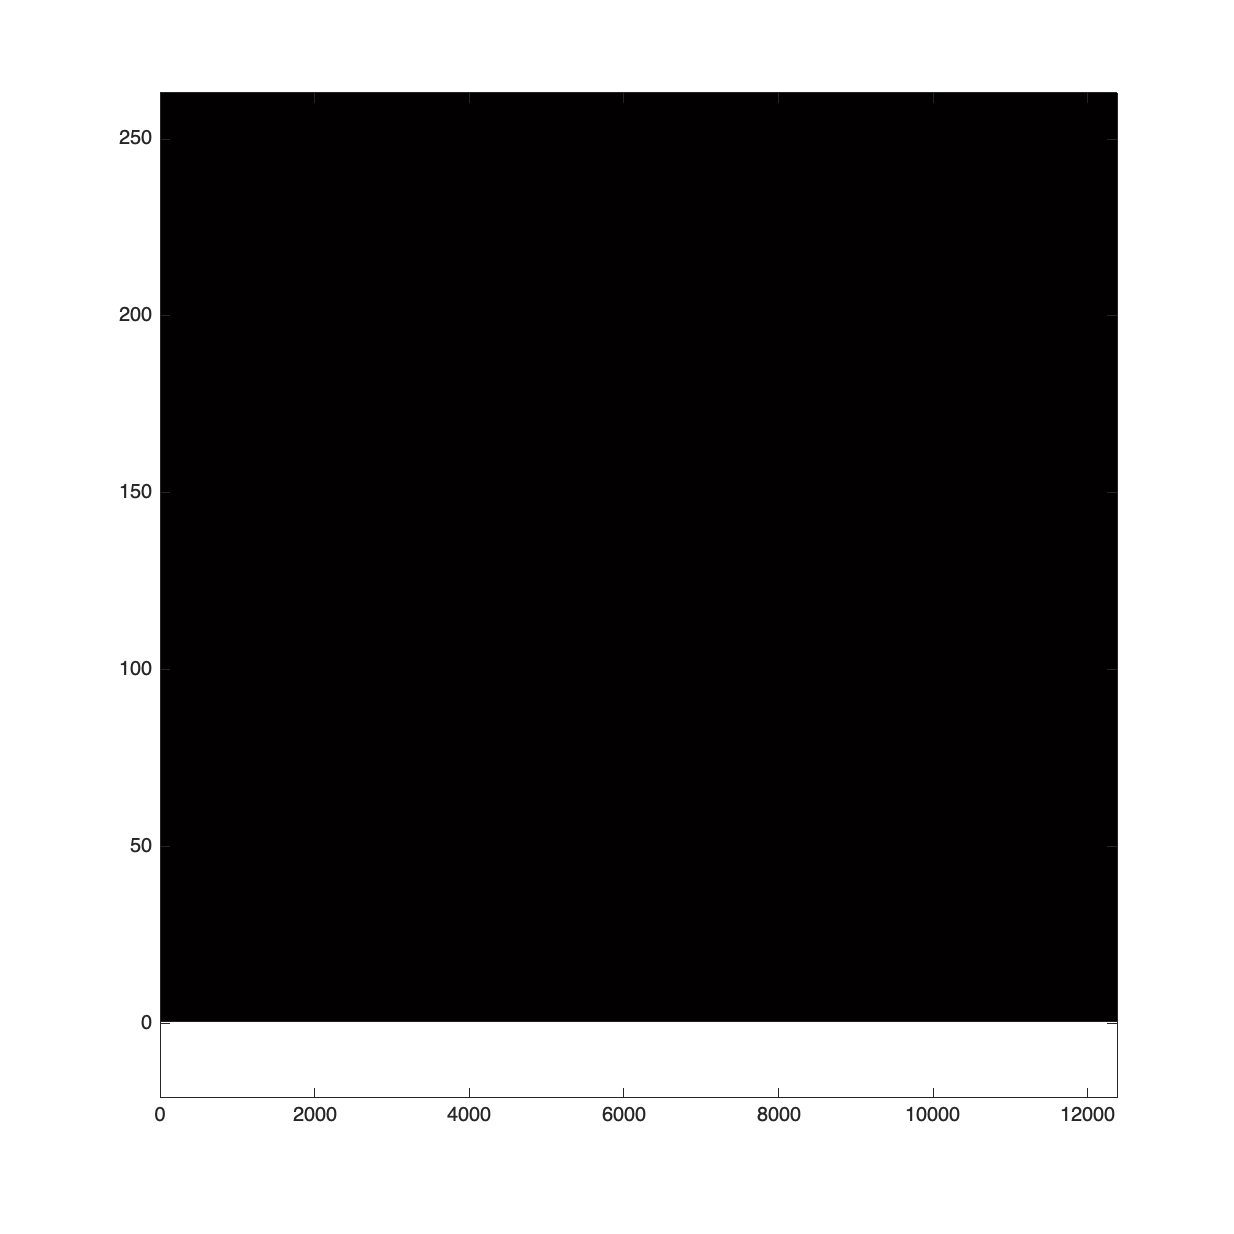


% hold off
% set(gcf, 'Position', [0, 0, 1000, 1000]);
% axis ([0 Nz -21 NCell])
% hold on
% for i = 1:length(TRace)
%     % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g');
%     % line(MovT(TRace(i))*[1 1],[0 NCell+1],'Color','g','LineWidth',0.1);
%     %text(TRace(i),1,'*','FontSize',20);
% end
% 
% hold off

%raster cells tSNE sorted run period
% [reduction, umap, clusterIdentifiers, extras]=run_umap(transpose(Tr1b));

TSNE=tsne(Race(:,:),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",50,...
    "Distance","correlation",'Perplexity',4,'Exaggeration',5);

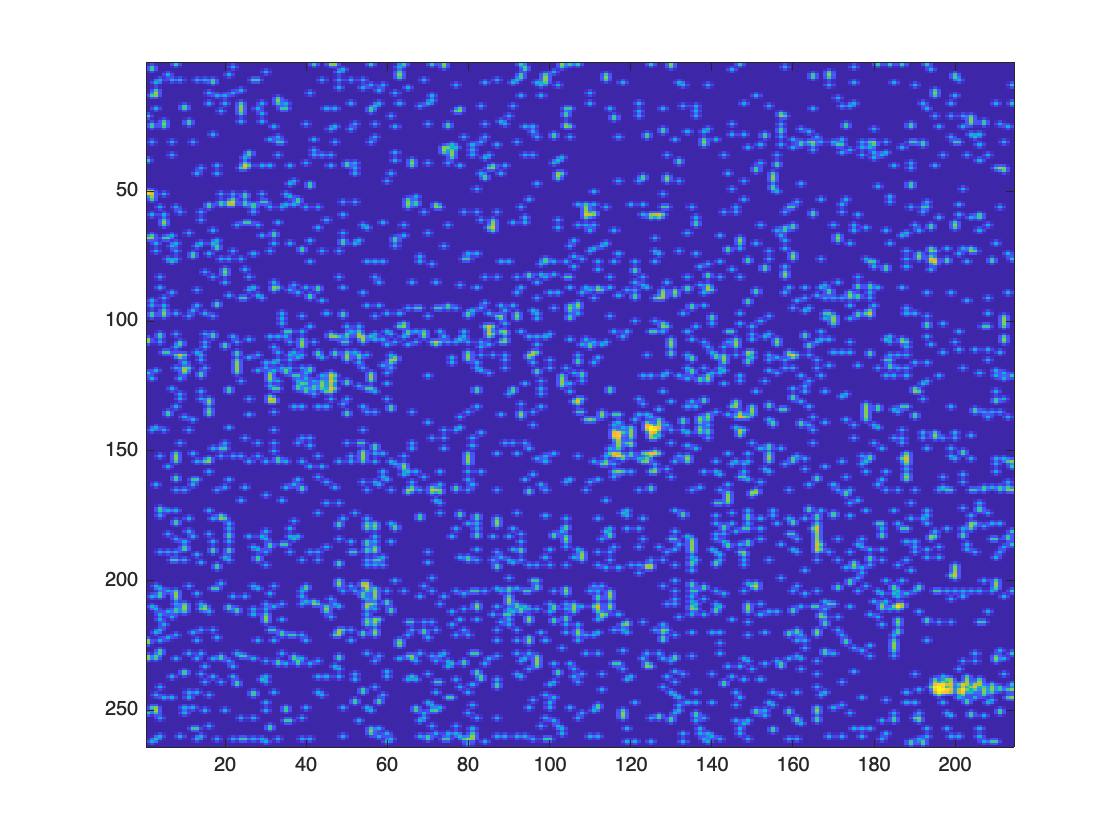

[B , index]=sort(TSNE);

figure
sortedRace=Race(index,:);
smtrace=smoothdata(sortedRace,1,'gaussian',3);
smtrace=smoothdata(smtrace,2,'gaussian',3);
imagesc(smtrace)

namegraph=[namefull 'RACE_tSNE_sorted_rastersmooth.png'];
exportgraphics(gcf,namegraph,'Resolution',300);
close gcf

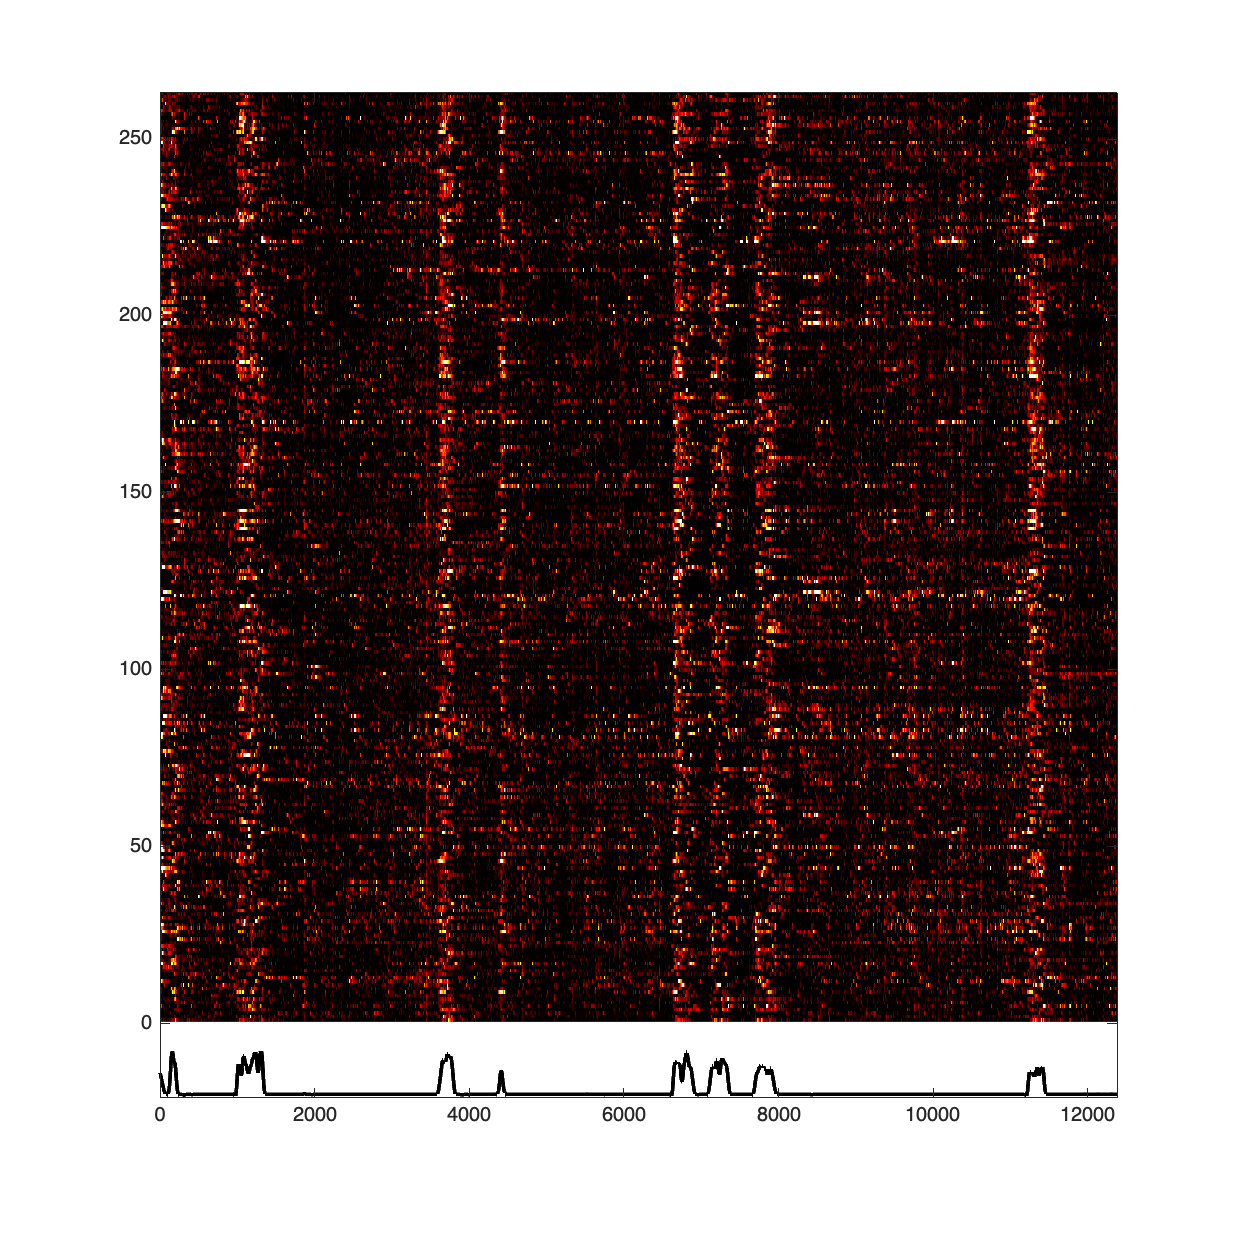

% TSNE=tsne(Tr1b(:,:),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",30,...
%     "Distance","correlation",'Perplexity',4,'Exaggeration',500);
% [B , index]=sort(TSNE);
% 
% figure
% smtrace=smoothdata(Tr1b,1,'gaussian',5);
% smtrace=smoothdata(smtrace,2,'gaussian',5);
% imagesc(smtrace(index,:))
% 
% colormap hot
% axis xy
% clim ([0 0.3])
% hold on
% plot (speed-20,'Color','k','LineWidth',2)
% hold off
% set(gcf, 'Position', [0, 0, 1000, 1000]);
% axis ([0 Nz -21 NCell])

%raster tsne running period
% TSNE=tsne(Tr1b(:,WinActive),"Algorithm","barneshut","NumDimensions",1,"NumPCAComponents",100,...
%     "Distance","correlation",'Perplexity',50,'Exaggeration',20);
% %[B , index]=sort(TSNE);
% [coeff,score,latent,~,explained,~]=pca(transpose(Tr1b(:,WinActive)));
% [B , index]=sort(coeff(:,1));

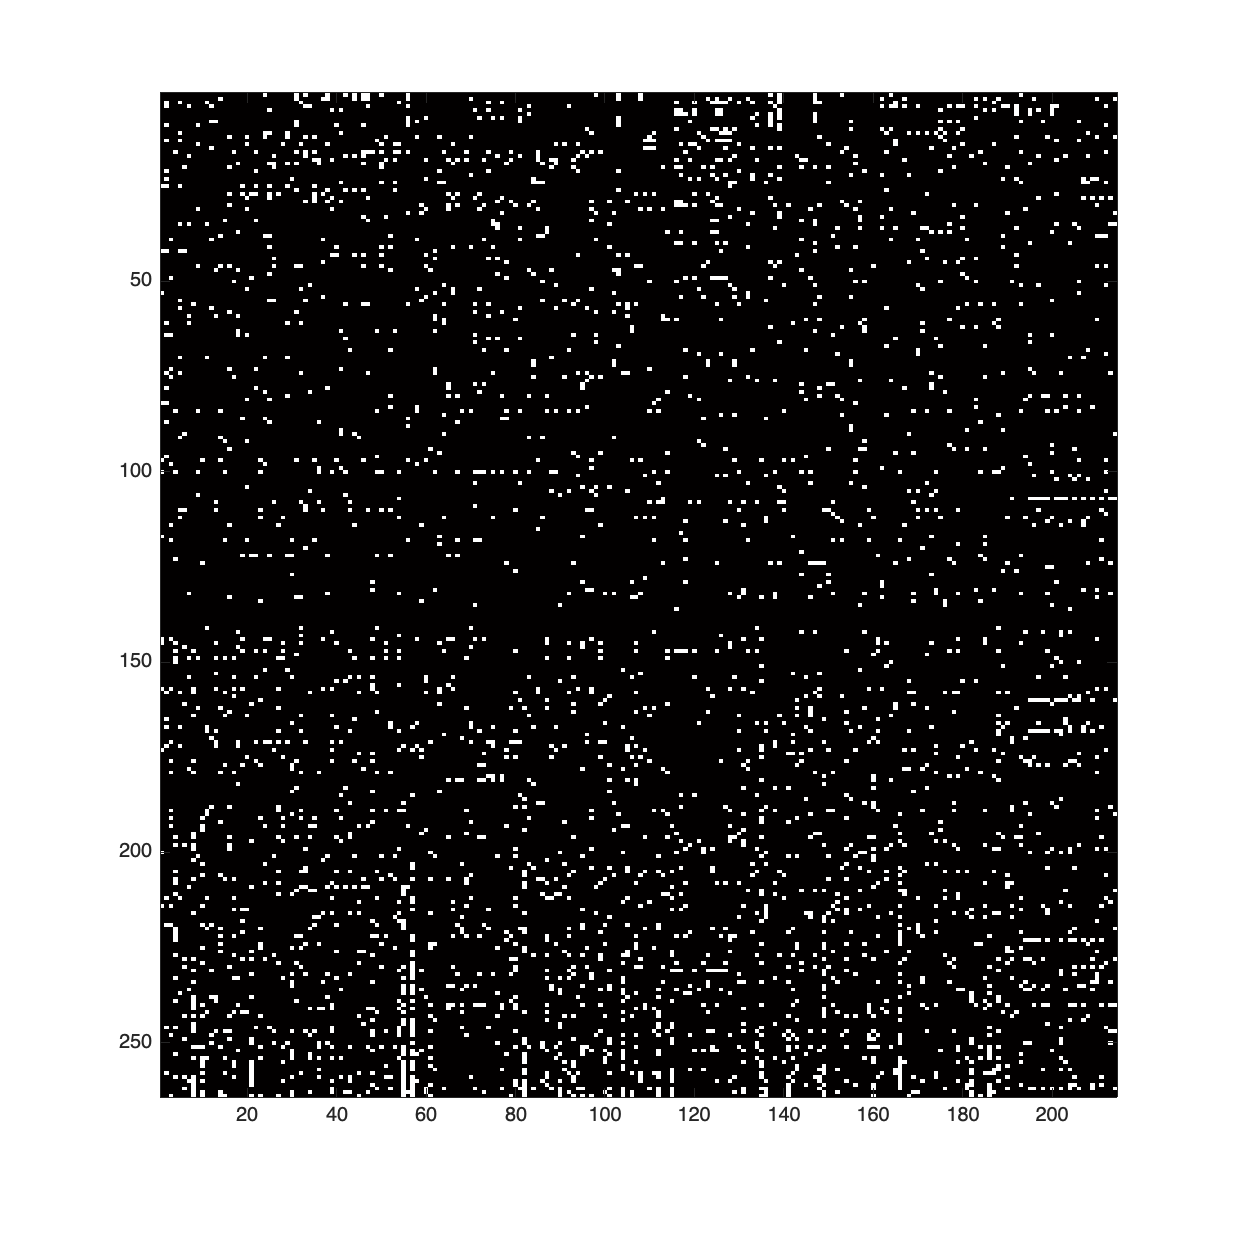

% [coeff,score,latent,~,explained,~]=pca(transpose(Race));
% [B , index]=sort(coeff(:,1));
% imagesc(Race(index,:))

 % [reduction, umap, clusterIdentifiers, extras]=run_umap(transpose(Race));

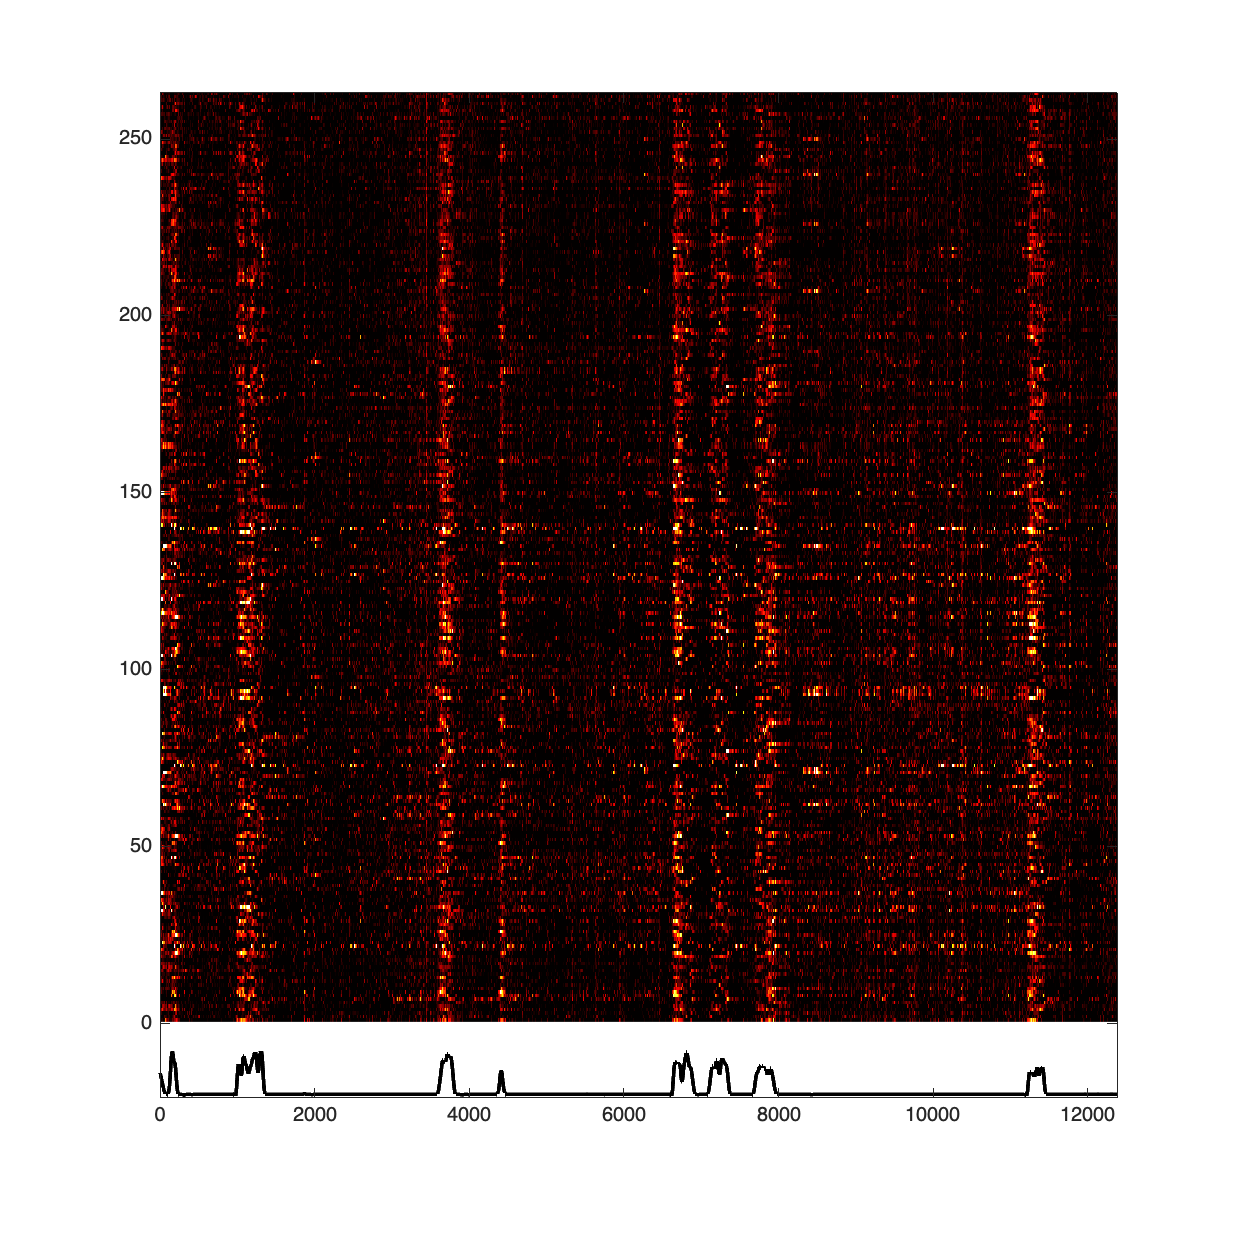

% %raster PCA 1
% figure
% smtrace=smoothdata(Tr1b,1,'gaussian',10);
% %smtrace=smoothdata(smtrace,2,'gaussian',5);
% imagesc(smtrace(index,:))
% colormap hot
% axis xy
% clim ([0 0.3])
% hold on
% plot (speed-20,'Color','k','LineWidth',2)
% hold off
% set(gcf, 'Position', [0, 0, 1000, 1000]);
% axis ([0 Nz -21 NCell])

% highspeed=find (speedraw>=1);
% lowspeed=find (speedraw<1);
% for n=1:length(speedraw)
%     if speedraw(n)>1
%         testspeed(n)=1;
%     else
%         testspeed(n)=0;
%     end
% end

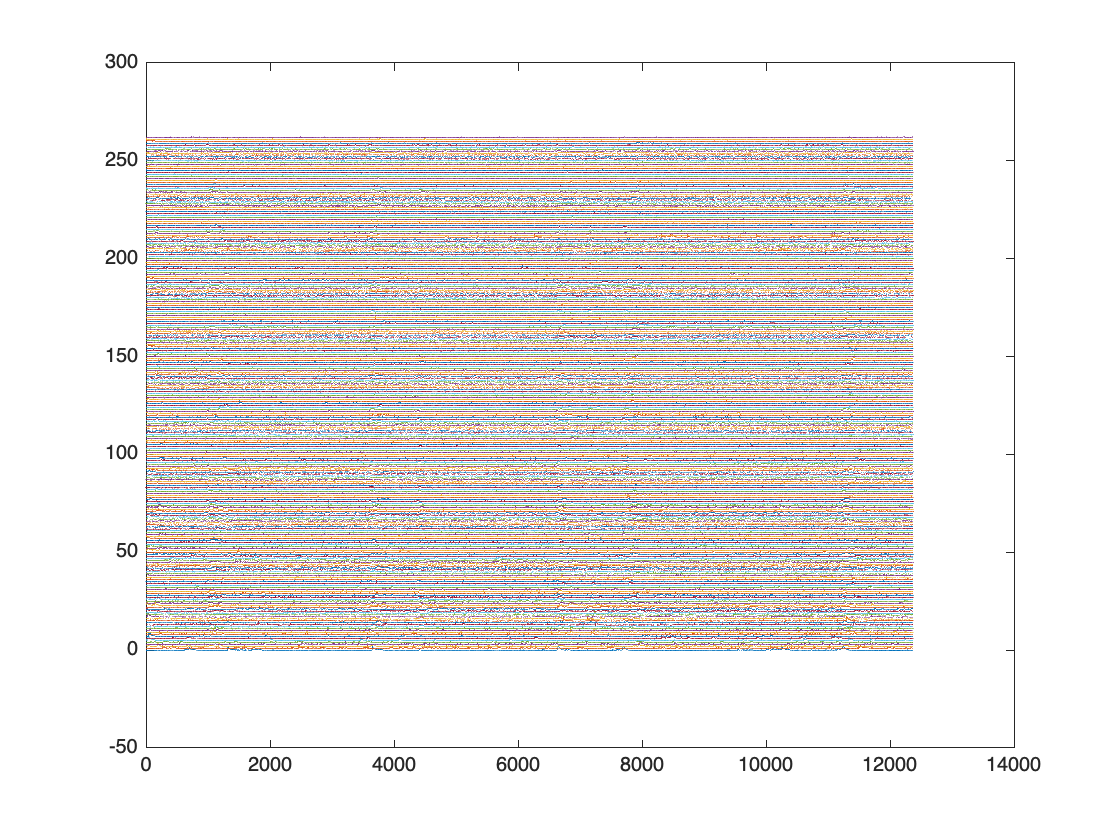

% figure
% for i = 1:NCell
%     % Raster(i,Acttmp2{i}) = 1;           %Raster = real raster of cell activity
%     plot(MovT,Tr1b(i,:)+i-1)
%     hold on
%     %plot(MovT(Acttmp2{i}),Tr1b(i,Acttmp2{i})+i-1,'.r')
% end

% figure 
% plot (MAct)
% hold on 
% plot(speed-10)


## sort raster per assembly

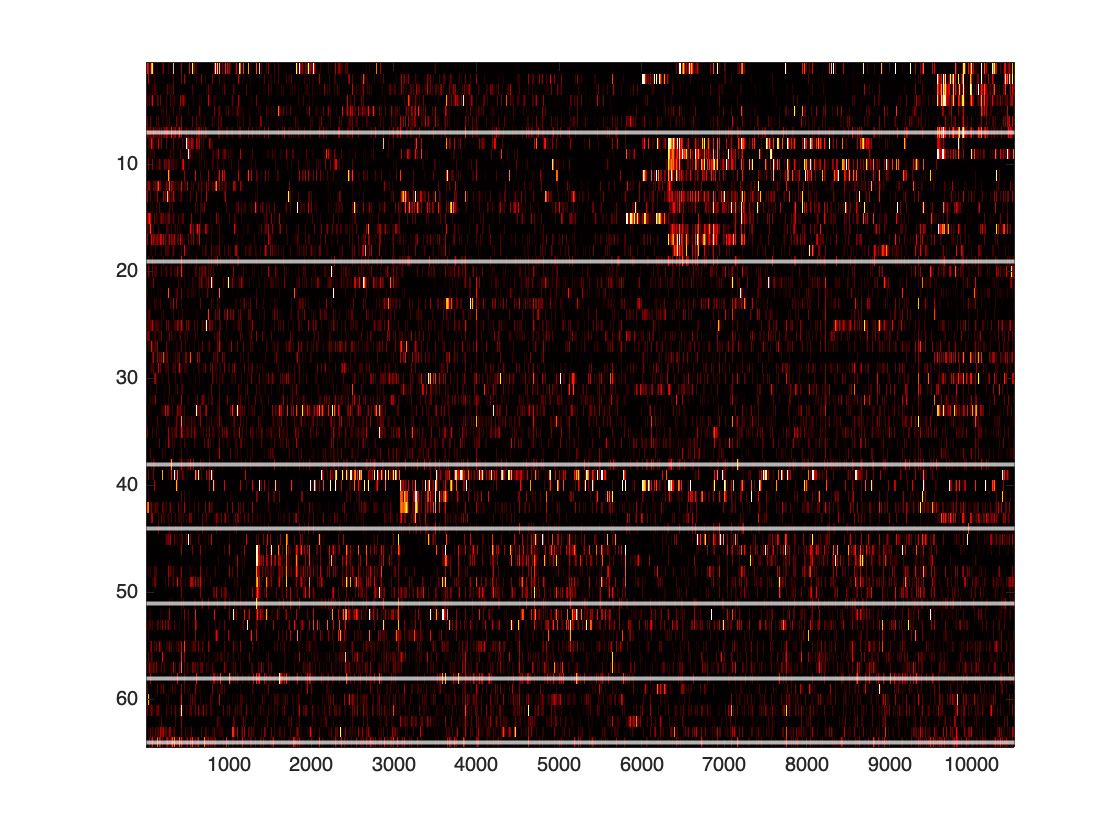


% [X1,x1] = sort(CellCl);
 % [~,x2] = sort(IDX2);
%smtrace=smoothdata(Tr1b,1,'gaussian',10);
figure
%smtrace=smoothdata(Tr1b,2,'gaussian',2);x
%smtrace=smoothdata(smtrace,2,'gaussian',5);
% imagesc(Tr1b(assemblyortho{1},WinRest))
DF=Tr1b(assemblyortho{1},WinRest);
listassembly=[];
for n=1:nbassemblies
    listassembly=[listassembly assemblyortho{n}];
end
% imagesc(Tr1b([assemblyortho{1} assemblyortho{2} assemblyortho{3} assemblyortho{4} assemblyortho{5} assemblyortho{6}],WinRest))
% smtrace=smoothdata(Tr1b(listassembly,WinRest),1,'gaussian',5);
% smtrace=smoothdata(smtrace,2,'gaussian',5);
% imagesc(smtrace)
imagesc(Tr1b(listassembly,WinRest))
colormap hot
%axis xy
clim ([0 0.4])
hold on
num=0;
for n=1:nbassemblies

    yline(length(assemblyortho{n})+num,'-r','LineWidth',2,'Color','w');
    num=num+length(assemblyortho{n});
end

%plot (-speed-1,'Color','k','LineWidth',2)
% axis ([0 Nz -22 num])
%clim ([0 0.4])
hold off
namegraph=[namefull 'assemblysortedraster.png'];
exportgraphics(gcf,namegraph,'Resolution',300);

close gcf

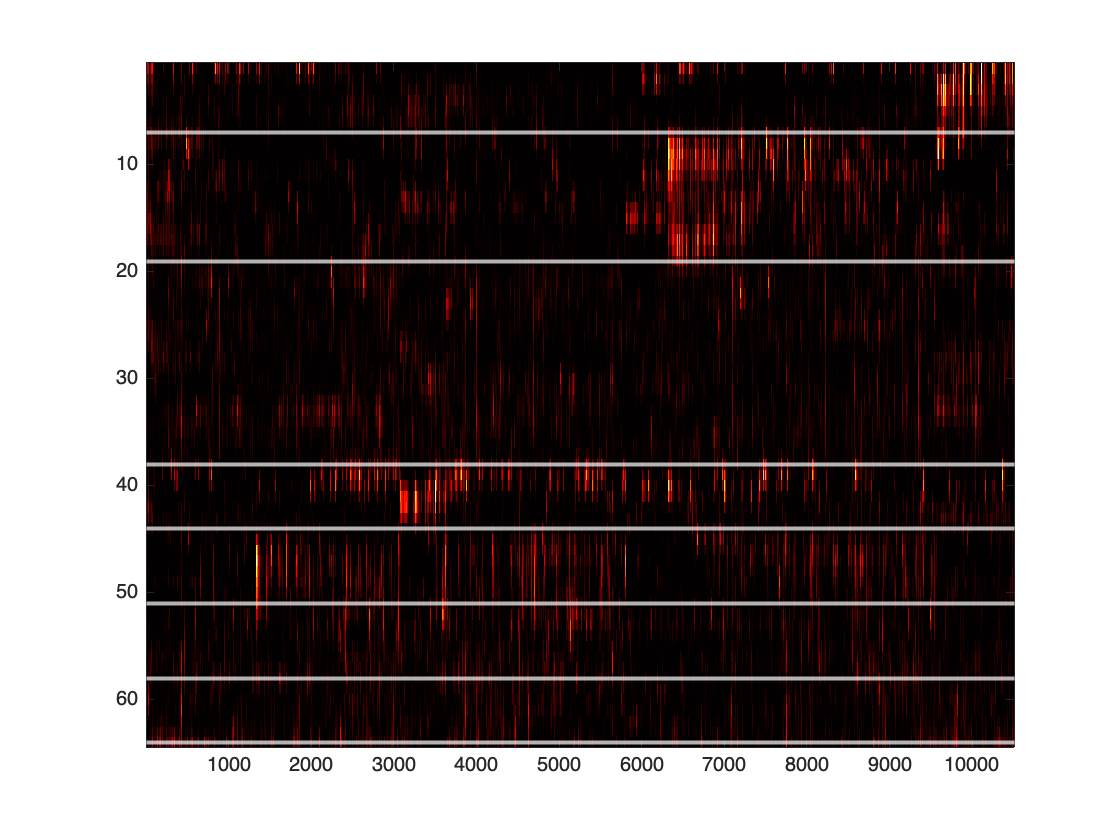

figure
%smtrace=smoothdata(Tr1b,2,'gaussian',2);x
%smtrace=smoothdata(smtrace,2,'gaussian',5);
% imagesc(Tr1b(assemblyortho{1},WinRest))
DF=Tr1b(assemblyortho{1},WinRest);
listassembly=[];
for n=1:nbassemblies
    listassembly=[listassembly assemblyortho{n}];
end
% imagesc(Tr1b([assemblyortho{1} assemblyortho{2} assemblyortho{3} assemblyortho{4} assemblyortho{5} assemblyortho{6}],WinRest))
smtrace=smoothdata(Tr1b(listassembly,WinRest),1,'gaussian',5);
smtrace=smoothdata(smtrace,2,'gaussian',5);
imagesc(smtrace)
%imagesc(Tr1b(listassembly,WinRest))
colormap hot
%axis xy
clim ([0 0.4])
hold on
num=0;
for n=1:nbassemblies

    yline(length(assemblyortho{n})+num,'-r','LineWidth',2,'Color','w');
    num=num+length(assemblyortho{n});
end

%plot (-speed-1,'Color','k','LineWidth',2)
% axis ([0 Nz -22 num])
%clim ([0 0.4])
hold off
namegraph=[namefull 'assemblysortedrastersmooth.png'];
exportgraphics(gcf,namegraph,'Resolution',300);

close gcf
return

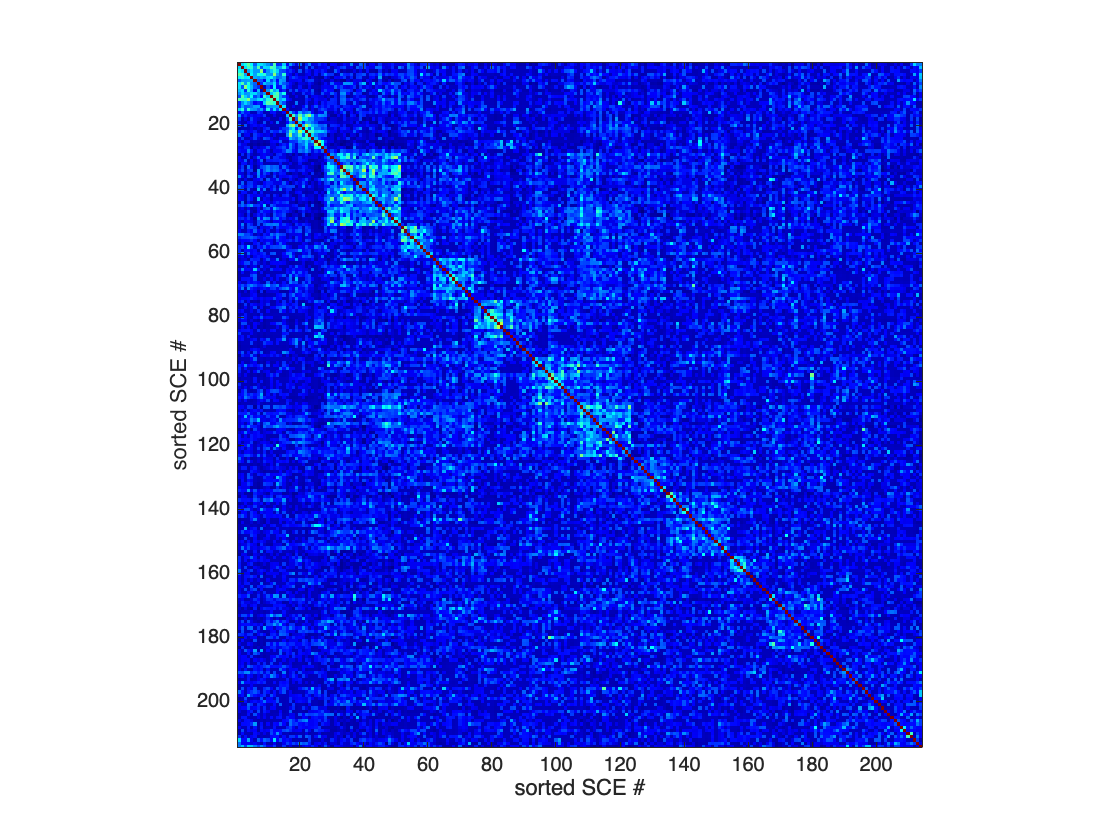

% subplot(1,2,1)
figure

imagesc(MSort)
colormap jet
axis image
xlabel('sorted SCE #')     %was RACE
ylabel('sorted SCE #')     %was RACE

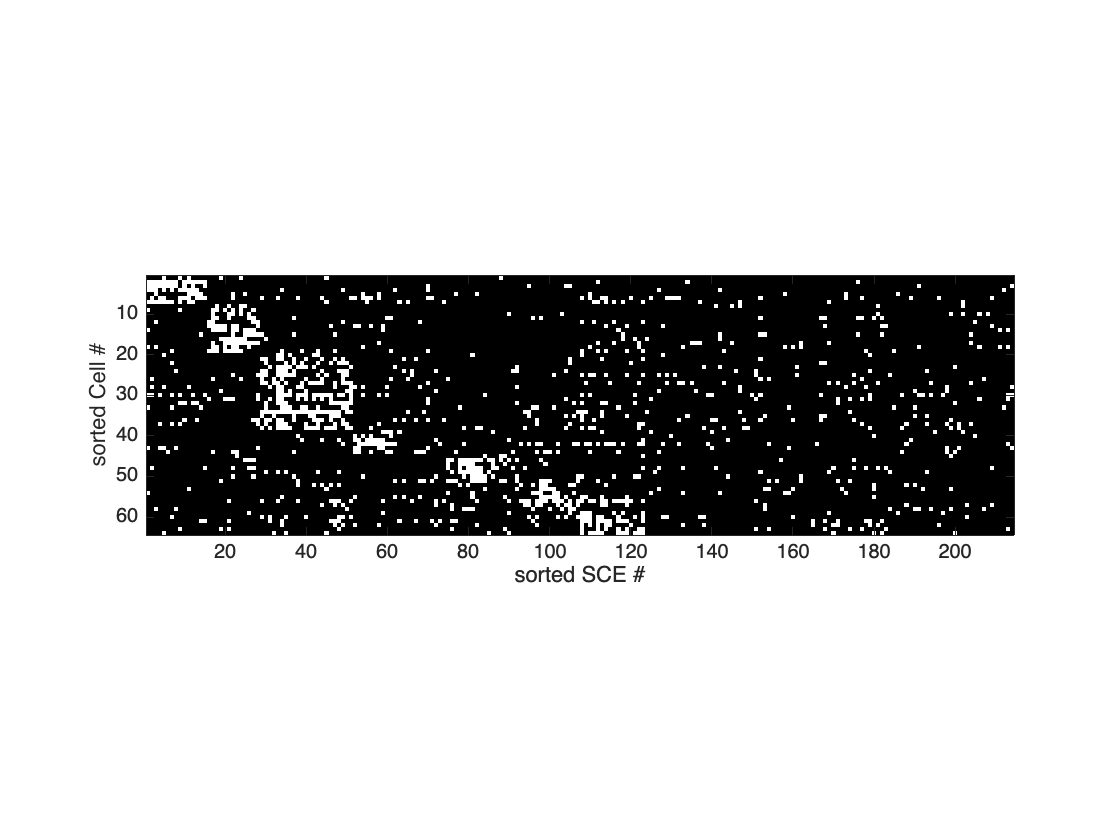

% 
% % subplot(1,2,2)
% figure
% list1=[];
% for n=1:   nbassemblies
%     list1=[list1 assembly{n}];
% end
% imagesc(Race(list1,x2))%,[-1 1.2])
% axis image
% xlabel('sorted SCE #')     %was RACE
% ylabel('sorted Cell #')
% colormap ("gray")

% for n=1:   nbassemblies
%     rectangle ('Position', [50, 250, 40, 40], 'EdgeColor', 'b', 'LineWidth', 2)
% end

% exportgraphics(gcf,[namefull 'clusters.png'],'Resolution',300)


% idassembly=zeros(NCell,1);
% listcellassembly=[];
% assembly=assemblyortho;
% %assembly=assemblystat;
% %assembly=assemblyraw;
% nbassemblies=length(assembly);
% 
% for n=1:nbassemblies
%     idassembly(assemblyortho{n})=n;
%     listcellassembly=[listcellassembly assemblyortho{n}];
%     sumSCEpercluster(n)=sum(IDX2==n);
% end
% 
% NCl = max(IDX2);
% [~,x2] = sort(IDX2);
% MSort = M(x2,x2);

    % 1 0 0;     % Red
    % 0 1 0;     % Green
    % 0 0 1;     % Blue
    % 1 1 0;     % Yellow
    % 1 0 1;     % Magenta
    % 0 1 1;     % Cyan
    % 0.5 0 0;   % Maroon
    % 0 0.5 0;   % Olive
    % 0 0 0.5;   % Navy
    % 0.5 0.5 0; % Olive Green
    % 0.5 0 0.5; % Purple
    % 0 0.5 0.5; % Teal
    % 0.75 0 0;  % Dark Red
    % 0 0.75 0;  % Lime Green
    % 0 0 0.75;  % Dark Blue
    % 0.75 0.75 0; % Dark Yellow
    % 0.75 0 0.75; % Dark Magenta
    % 0 0.75 0.75; % Dark Cyan
    colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];


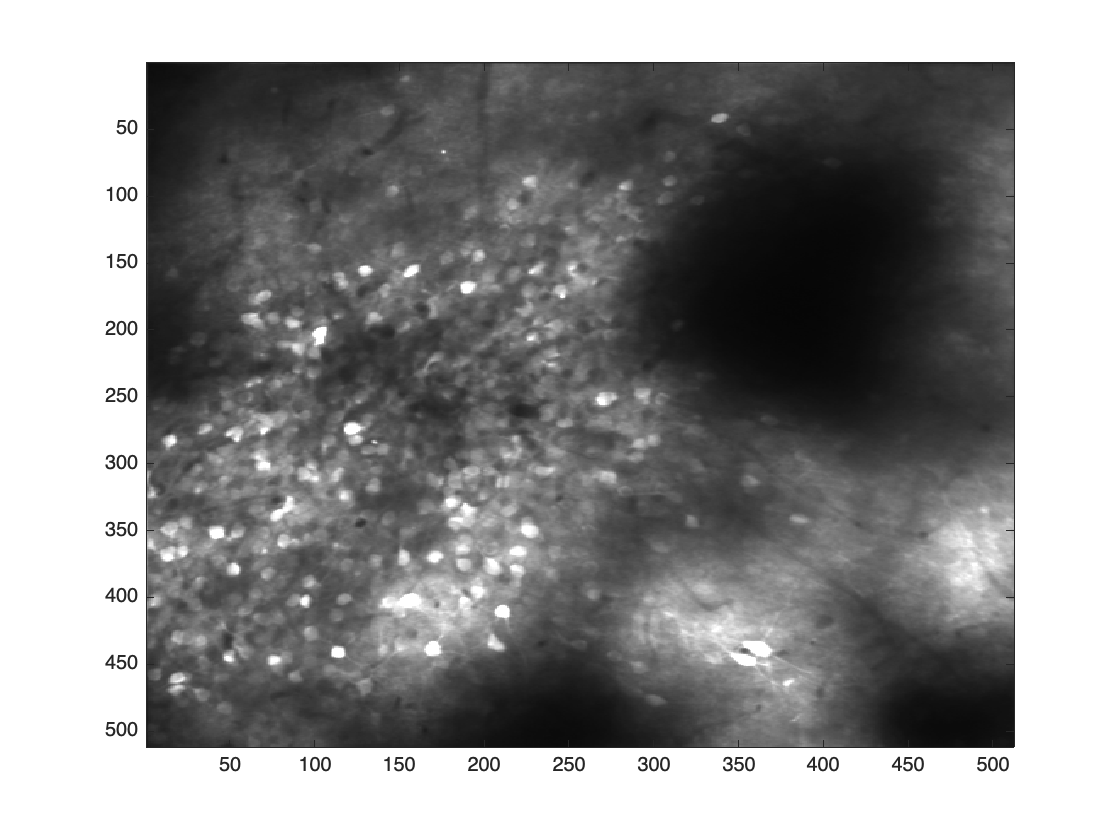


figure

imagesc(calcium);
colormap (gray)
clim ([0 300])

hold on


for n=1:NCell

    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    % if idassembly(n)==1 ; color=  [1 0 0];     % Red
    % elseif idassembly(n)==2 ; color=  [ 0 1 0]; % green
    % elseif idassembly(n)==3 ; color=  [0 0 1]; % blue
    % elseif idassembly(n)==4 ; color=  [1 1 0]; % yellow
    % elseif idassembly(n)==5 ; color=  [1 0 1]; % magenta
    % elseif idassembly(n)==6 ; color=  [0 1 1]; % cyan
    % elseif idassembly(n)==7 ; color=  [0.5 0 0];%  Maroon
    % elseif idassembly(n)==8 ; color=  [0 0.5 0];%  Olive
    % elseif idassembly(n)==9 ; color=  [0 0 0.5]; % Navy
    % elseif idassembly(n)==10 ; color=  [0.5 0.5 0]; % Olive Green
    % elseif idassembly(n)==11 ; color=  [0.5 0 0.5]; % Purple 
    % % elseif assembly==7 ; color='white'
    % % elseif assembly==8 ; color='blue'
    % % elseif assembly==9 ; color='blue'
    % % elseif assembly==10 ; color='blue'
    % % elseif assembly==11 ; color='blue'
    % % elseif assembly==12 ; color='blue'
    % % elseif assembly==13 ; color='blue'
    % % elseif assembly==14 ; color='blue'
    % % elseif assembly==15 ; color='blue'
    % % elseif assembly==16 ; color='blue'
    % % elseif assembly==17 ; color='blue'
    % % elseif assembly==18 ; color='blue'
    % 
    % 
    % else
    %     color='white';
    % end

    plot(x, y, '.', 'MarkerSize', 4,"Color",colors(idassembly(n),:));
   % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.


axis image
axis off
hold off
title ('calcium')

figure

imagesc(calcium);
colormap (gray)
clim ([0 300])

hold on

for n=1:NCell

    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    % if idassembly(n)==1 ; color=  [1 0 0];     % Red
    % elseif idassembly(n)==2 ; color=  [ 0 1 0]; % green
    % elseif idassembly(n)==3 ; color=  [0 0 1]; % blue
    % elseif idassembly(n)==4 ; color=  [1 1 0]; % yellow
    % elseif idassembly(n)==5 ; color=  [1 0 1]; % magenta
    % elseif idassembly(n)==6 ; color=  [0 1 1]; % cyan
    % elseif idassembly(n)==7 ; color=  [0.5 0 0];%  Maroon
    % elseif idassembly(n)==8 ; color=  [0 0.5 0];%  Olive
    % elseif idassembly(n)==9 ; color=  [0 0 0.5]; % Navy
    % elseif idassembly(n)==10 ; color=  [0.5 0.5 0]; % Olive Green
    % elseif idassembly(n)==11 ; color=  [0.5 0 0.5]; % Purple 
    % % elseif assembly==7 ; color='white'
    % % elseif assembly==8 ; color='blue'
    % % elseif assembly==9 ; color='blue'
    % % elseif assembly==10 ; color='blue'
    % % elseif assembly==11 ; color='blue'
    % % elseif assembly==12 ; color='blue'
    % % elseif assembly==13 ; color='blue'
    % % elseif assembly==14 ; color='blue'
    % % elseif assembly==15 ; color='blue'
    % % elseif assembly==16 ; color='blue'
    % % elseif assembly==17 ; color='blue'
    % % elseif assembly==18 ; color='blue'
    % 
    % 
    % else
    %     color='white';
    % end
    plot(x, y, '.', 'MarkerSize', 4,"Color",colors(idassembly(n),:));
   % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
end

axis image
axis off
hold off
title ('calcium')

figure
imagesc(MSort)
colormap jet
axis image
xlabel('sorted SCE #')     %was RACE
ylabel('sorted SCE #')     %was RACE

testCellCl=CellCl

testCellCl =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0

[X1,x1] = sort(CellCl);  %x1 list cellule
%nbcellassembly=


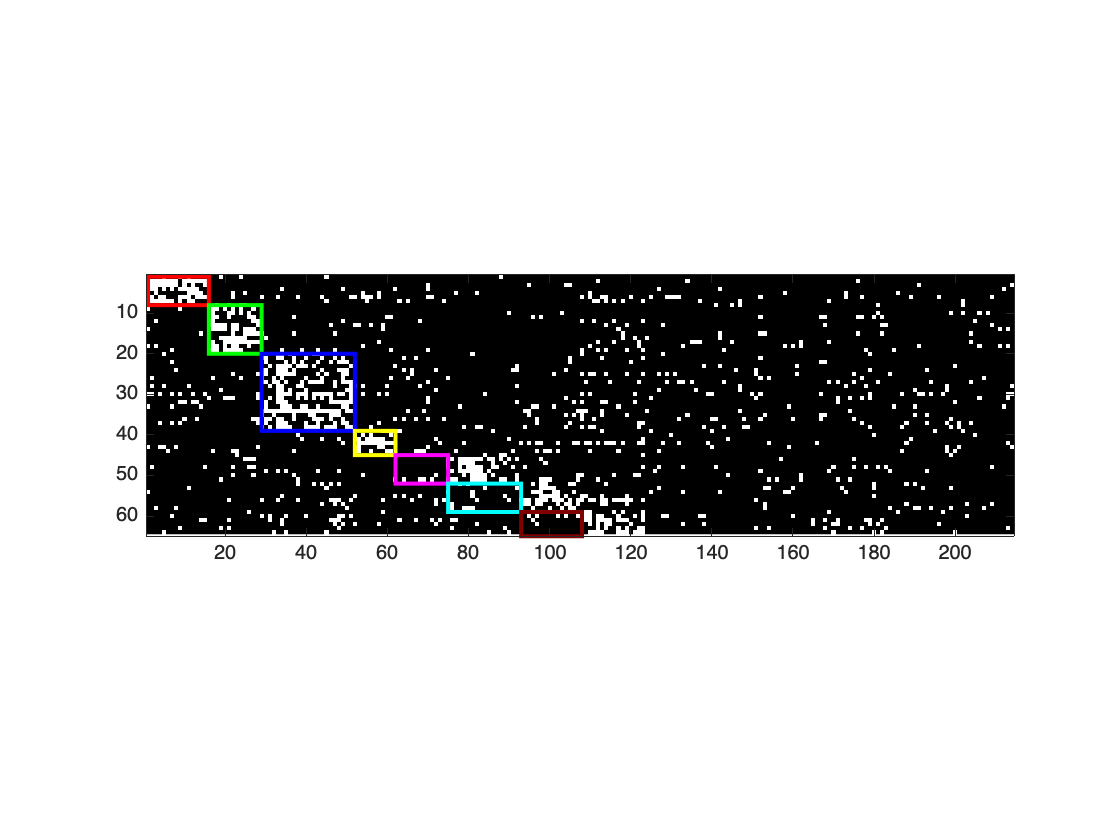

figure

colormap gray
imagesc(Race(listcellassembly,x2))%,[-1 1.2])
hold on
% imagesc(Race(x1,x2))%,[-1 1.2])
axis image
x=1;
y=1;

for n=1 : nbassemblies

    width=sumSCEpercluster(n);
    height=length(assemblyortho{n});
    rectangle('Position', [x, y, width, height], 'EdgeColor', colors(n,:), 'LineWidth', 2);
    x=x+width;
    y=y+height;

end

hold off

% for n=1:5
%     if n==1 ; color=  [1 0 0];     % Red
%         elseif n==2 ; color=  [ 0 1 0]; % green
%         elseif n==3 ; color=  [0 0 1]; % blue
%         elseif n==4 ; color=  [1 1 0]; % yellow
%         elseif n==5 ; color=  [1 0 1]; % magenta
%     end
% end

% rectangle('Position', [sumSCEpercluster(1)+1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);
% rectangle('Position', [1, 1, sumSCEpercluster(1), length(assemblyortho{1})], 'EdgeColor', 'r', 'LineWidth', 2);




i=0;
figure
% axis image
hold on
for n=1:10%x1
    Race(n,:)>0,i
    t=Race(n,:)>0
    rectangle ('Position', [50, 250, 40, 40], 'EdgeColor', 'b', 'LineWidth', 2)
    i=i+1;
    
end

ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 0

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0


i = 1

t = 1×214 logical array
   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 2

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 3

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 4

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 5

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 6

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 7

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 8

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ans = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


i = 9

t = 1×214 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


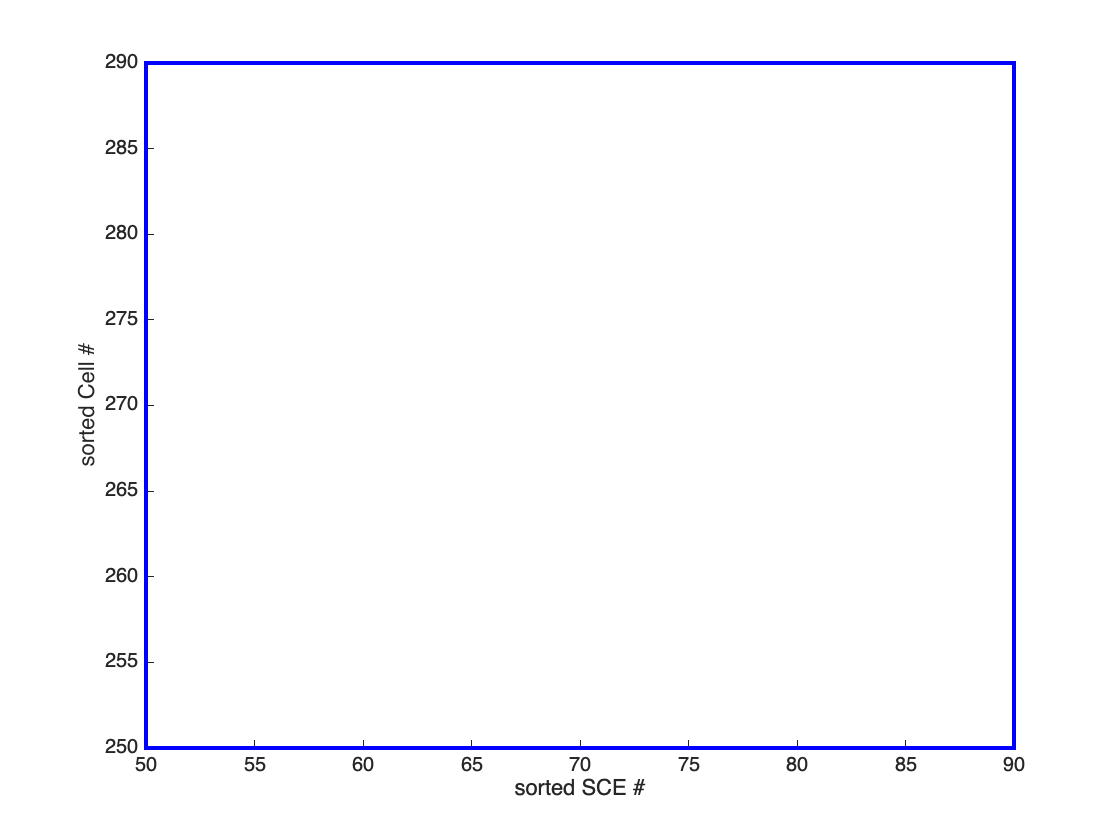

hold off

xlabel('sorted SCE #')     %was RACE
ylabel('sorted Cell #')

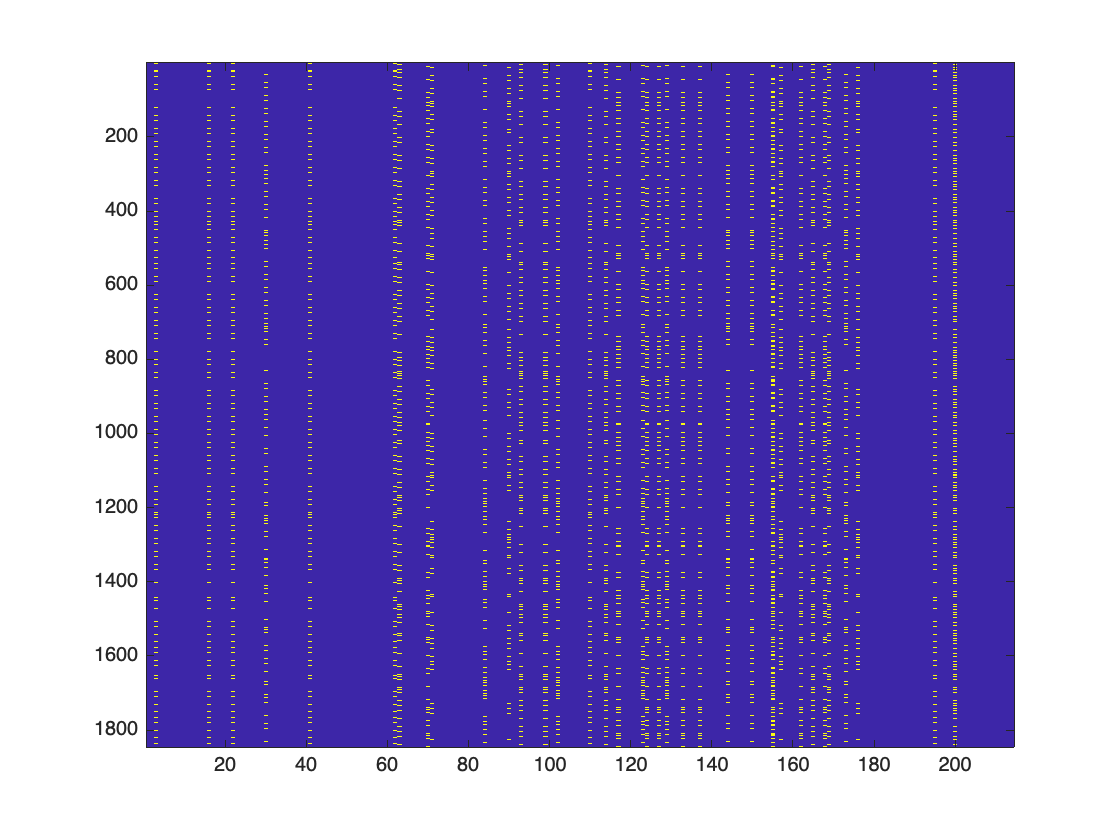

figure
imagesc(Race(x1,:))